clear
clc
close all

syms Ki Kp Kd s Gc1 Gc2 a b
K = 2;
A = s+1;
B = s^3+8*s^2+15*s;
Psym = K*A/B

$$Psym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

Csym = (Kp*s + Ki + Kd*s^2)/s * 1/(A)

$$Csym = \frac{\mathrm{Kd}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}{s\,\left(s+1\right)}$$

GYDsym = s*A/(s*B + (Kp*s + Ki + Kd*s^2)*K)

$$GYDsym = \frac{s\,\left(s+1\right)}{2\,\mathrm{Ki}+s\,\left(s^{3}+8\,s^{2}+15\,s\right)+2\,\mathrm{Kp}\,s+2\,\mathrm{Kd}\,s^{2}}$$

GYRsym = collect(Gc1*Psym/(1+Csym*Psym),s)

$$GYRsym = \frac{\left(2\,{\mathrm{Gc}}_{1}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1}\right)\,s}{s^{4}+8\,s^{3}+\left(2\,\mathrm{Kd}+15\right)\,s^{2}+\left(2\,\mathrm{Kp}\right)\,s+2\,\mathrm{Ki}}$$

[num,den] = numden(GYRsym)

$$num = 2\,{\mathrm{Gc}}_{1}\,s^{2}+2\,{\mathrm{Gc}}_{1}\,s$$

$$den = 2\,\mathrm{Ki}+2\,\mathrm{Kp}\,s+2\,\mathrm{Kd}\,s^{2}+15\,s^{2}+8\,s^{3}+s^{4}$$

den = collect(den)

$$den = s^{4}+8\,s^{3}+\left(2\,\mathrm{Kd}+15\right)\,s^{2}+\left(2\,\mathrm{Kp}\right)\,s+2\,\mathrm{Ki}$$

coeffs_den = coeffs(den, s, 'All')

$$coeffs\_den = \left(\begin{array}{ccccc} 1 & 8 & 2\,\mathrm{Kd}+15 & 2\,\mathrm{Kp} & 2\,\mathrm{Ki} \end{array}\right)$$

w = coeffs_den(end-2:end)

$$w = \left(\begin{array}{ccc} 2\,\mathrm{Kd}+15 & 2\,\mathrm{Kp} & 2\,\mathrm{Ki} \end{array}\right)$$

w = sum(w.*s.^[2 1 0])

$$w = \left(2\,\mathrm{Kd}+15\right)\,s^{2}+2\,\mathrm{Kp}\,s+2\,\mathrm{Ki}$$

Gc1 = w/(K*A*s)

$$Gc1 = \frac{\left(2\,\mathrm{Kd}+15\right)\,s^{2}+2\,\mathrm{Kp}\,s+2\,\mathrm{Ki}}{s\,\left(2\,s+2\right)}$$

Gc2 = simplify(Csym-Gc1)

$$Gc2 = -\frac{15\,s}{2\,\left(s+1\right)}$$

Encontrar los coeficientes

z = 0.2;
ts = 1;
%wn = 4/(z*ts)
wn = 15;
b = 1;
poli_2do_orden1 = s^2 + 2*z*wn*s + wn^2;
poli_2do_orden2 = s^2 + a*s + b;
polinomio_deseado = poli_2do_orden1*poli_2do_orden2;
coeffs_deseado = coeffs(expand(polinomio_deseado), s, 'All')

$$coeffs\_deseado = \left(\begin{array}{ccccc} 1 & a+6 & 6\,a+226 & 225\,a+6 & 225 \end{array}\right)$$

Resolución de sistema de ecuaciones

eqs = [coeffs_den(2:5)] == [coeffs_deseado(2:5)]

$$eqs = \left(\begin{array}{cccc} 8=a+6 & 2\,\mathrm{Kd}+15=6\,a+226 & 2\,\mathrm{Kp}=225\,a+6 & 2\,\mathrm{Ki}=225 \end{array}\right)$$

S = solve(eqs, [Ki, Kp, Kd, a]);
Ki = double(S.Ki(1))

Ki = 112.5000

Kp = double(S.Kp(1))

Kp = 228

Kd = double(S.Kd(1))

Kd = 111.5000

a = double(S.a(1))

a = 2

%b = double(S.b(1))

Numéricamente

numPlanta =[1 1];
K = 2;
denPlanta = [1 8 15 0];
P = tf(K*numPlanta, denPlanta)

P =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



C = tf([Kd Kp Ki], [numPlanta,0])

C =
 
  111.5 s^2 + 228 s + 112.5
  -------------------------
           s^2 + s
 
Continuous-time transfer function.



[numGc2,denGc2] = numden(Gc2);
numGc2 = sym2poly(numGc2);
denGc2 = sym2poly(denGc2);
Gc2 = tf(numGc2,denGc2)

Gc2 =
 
   -15 s
  -------
  2 s + 2
 
Continuous-time transfer function.



Gc1 = C - Gc2

Gc1 =
 
  238 s^3 + 694 s^2 + 681 s + 225
  -------------------------------
        2 s^3 + 4 s^2 + 2 s
 
Continuous-time transfer function.



GYD = feedback(P,C)

GYD =
 
               2 s^3 + 4 s^2 + 2 s
  ---------------------------------------------
  s^5 + 9 s^4 + 246 s^3 + 694 s^2 + 681 s + 225
 
Continuous-time transfer function.



GYR = GYD * Gc1

GYR =
 
          476 s^6 + 2340 s^5 + 4614 s^4 + 4562 s^3 + 2262 s^2 + 450 s
  ----------------------------------------------------------------------------
  2 s^8 + 22 s^7 + 530 s^6 + 2390 s^5 + 4630 s^4 + 4562 s^3 + 2262 s^2 + 450 s
 
Continuous-time transfer function.



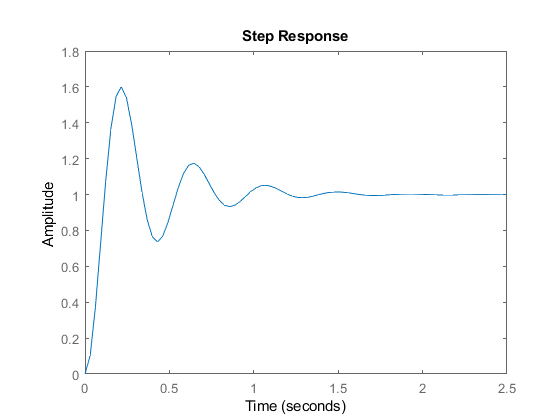

step(GYR)

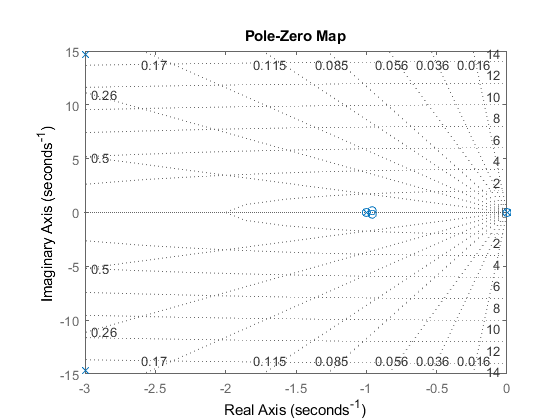

pzmap(GYR)
grid on

stepinfo(GYR)

ans = struct with fields:
        RiseTime: 0.0778
    SettlingTime: 1.1617
     SettlingMin: 0.7363
     SettlingMax: 1.6005
       Overshoot: 60.0520
      Undershoot: 0
            Peak: 1.6005
        PeakTime: 0.2149


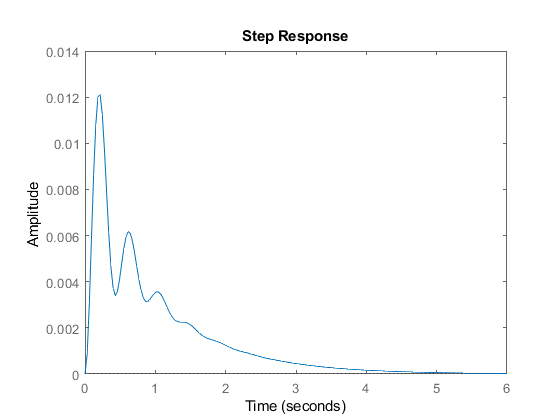

step(GYD)

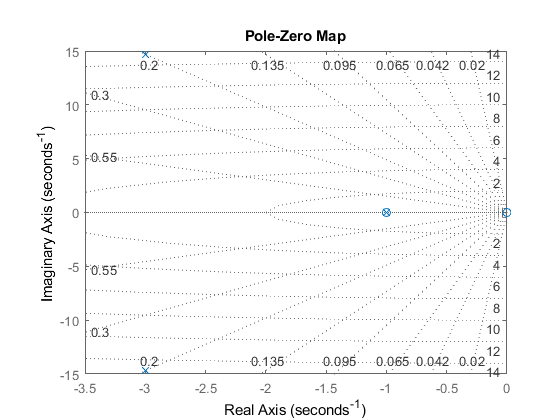

pzmap(GYD)
grid on

stepinfo(GYD)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 3.6257
     SettlingMin: 2.0196e-05
     SettlingMax: 0.0121
       Overshoot: Inf
      Undershoot: 0
            Peak: 0.0121
        PeakTime: 0.2149


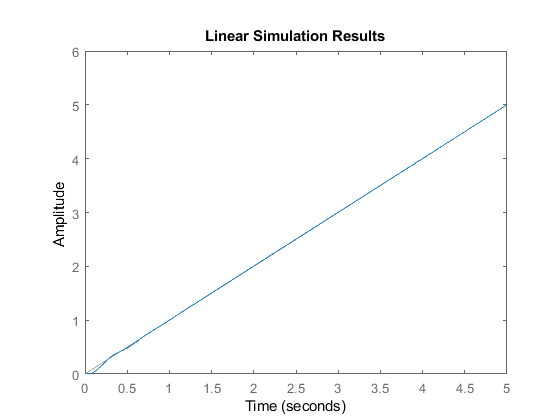

vt = 0:0.01:5;
u = vt;
lsim(GYR,u,vt)

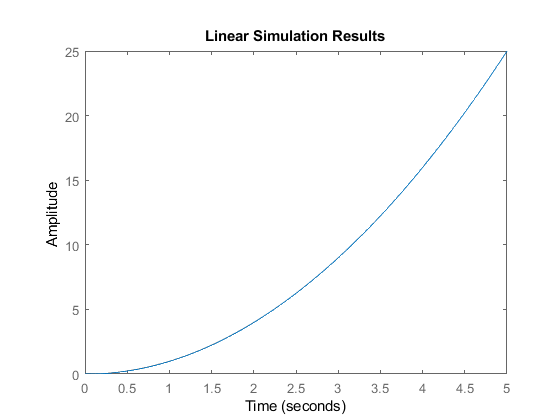

u = vt.^2;
lsim(GYR,u,vt)